%clc,clear
load('ECGdn_upsampled.mat', ...
     'ECGdn', 'Fs', 't', ...
     'ECGdn_up_spline', ...
     'ECGdn_up_resample', ...
     'Fs_up', 't_up')

fd = ECGdn_up_spline(:);
td = t_up(:);
td = td - mean(td);


N = length(fd);

% Time axis centered around zero
%td = (-(N-1)/2 : (N-1)/2);
td = td(:);
%alpha = 0.4;
%kappa = 5600;
alpha=0.15;
kappa=5600;
Fm = 100;
c1 = 1;
shift=3.2;
%shift = 2.2;
%c1 = 1;
%shift = 4.2;
BW = 2 * pi * Fm;


 %% --- Input conditioning ---
    fd = fd(:);
    td = td(:);

    % Remove NaNs just in case
    valid = isfinite(fd) & isfinite(td);
    fd = fd(valid);
    td = td(valid);

    % Apply shift
    fd = fd + shift;

    %% --- Time parameters ---
    dt   = td(2) - td(1);
    Tmin = td(1);
    Tmax = td(end);

    %% --- Numerical safety (SOFT floors, dt-aware) ---
    %eps_dt = 1e-8 * dt;
    eps_dt=0;
    %% --- Initialization ---
    current_time = Tmin;
    current_index = 1;

    running_integral        = 0;
    signal_running_integral = 0;
    running_area            = 0;

    integral_value = 0;
    sum_bias       = 0;
    time_gap       = 0;

    %% --- Storage ---
    tn           = [];
    time_stamps  = [Tmin];
    f_n          = [shift];
    loc          = [];

    %% ================= MAIN LOOP ====================
    while current_index < length(fd) && current_time <= Tmax

        %% --- Energy accumulation ---
        df = (fd(current_index+1) - fd(current_index)) / dt;

        running_integral = running_integral + df^2 * dt;
        signal_running_integral = signal_running_integral + fd(current_index)^2 * dt;
        running_area = running_area + fd(current_index)^2 * dt;

        %% --- Soft safety floors (do NOT flatten dynamics) ---
        ri = max(running_integral, eps_dt);
        si = max(signal_running_integral, eps_dt);
        ra = max(running_area, eps_dt);

        %% --- Adaptive threshold ---
        running_delta = 1 / sqrt(ri + kappa * si);

        %% --- Adaptive bias ---
        a = sqrt(ra);
        running_area1 = 1 / (pi * sqrt(alpha) * a);

        % Soft cap to prevent uniform behavior
        %running_area1 = min(running_area1, 600);

        running_bias = c1 + running_area1;

        %% --- Integrate biased signal ---
        integral_value = integral_value + fd(current_index) * dt + running_bias * dt;
        sum_bias       = sum_bias + running_bias * dt;
        time_gap       = time_gap + dt;

        %% --- Fire condition ---
        if abs(integral_value) >= running_delta

            tn  = [tn; current_time];
            loc = [loc; current_index];

            time_stamps = [time_stamps; time_gap];

            % Encoded value
            f_n = [f_n; (integral_value - sum_bias) / time_gap];

            %% --- Reset ---
            integral_value = 0;
            sum_bias       = 0;
            time_gap       = 0;

            running_integral        = 0;
            signal_running_integral = 0;
            running_area            = 0;
        end

        %% --- Increment ---
        current_index = current_index + 1;
        current_time  = current_time + dt;
    end

    %% --- Output ---
    NoF = length(tn)

NoF = 1837

iter=5;
F_est = reconstruction_running_func(NoF, td, f_n-shift, time_stamps, loc, tn, BW, Fm, iter);%%

%k = 0;

% Right shift column 25
%F_est(:,iter) = [zeros(k,1); F_est(1:end-k,iter)];

% Normalize
F_est(:,iter) = F_est(:,iter) / max(abs(F_est(:,iter)));



% Error metric
err = 10*log10( ...
    norm(fd(200:end-500)-shift - F_est(200:end-500,iter))^2 / ...
    norm(fd(200:end-500)-shift)^2 )

err = -31.9514


%10 * log10( norm(fd(2000:end-1000) - F_est(2000:end-1000,iter))^2 )
disp(['Length of td: ', num2str(length(td))]);

Length of td: 100000


disp(['Length of fd: ', num2str(length(fd))]);

Length of fd: 100000


disp(['Size of F_est: ', mat2str(size(F_est))]);

Size of F_est: [100000 5]


disp(['iter: ', num2str(iter)]);

iter: 5


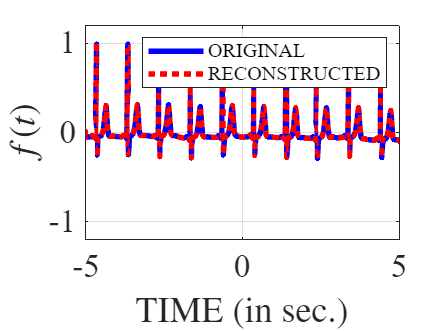



figure;
plot(td, (fd-shift)-mean(fd-shift), 'b', 'DisplayName', 'ORIGINAL', 'LineWidth', 3); hold on;
plot(td, F_est(:,iter), 'r:', 'DisplayName', 'RECONSTRUCTED', 'LineWidth', 3); 

xlabel('TIME (in sec.)','FontSize',18,'FontName','Times','Interpreter','Latex');
ylabel('$f(t)$','FontSize',18,'FontName','Times','Interpreter','Latex');
set(gca,'FontSize',18,'FontName','Times');
legend('FontSize', 11);
grid on;
xlim([-5, 5]);  
ylim([-1.2, 1.2]);  

%exportgraphics(gcf, 'real_signal.pdf', 'ContentType', 'vector', 'BackgroundColor', 'none', 'Resolution', 300);


disp(abs(max(td)));

    4.9990



disp(pi*sqrt(alpha/kappa));

    0.0163



disp(1/(2*Fm));

    0.0050



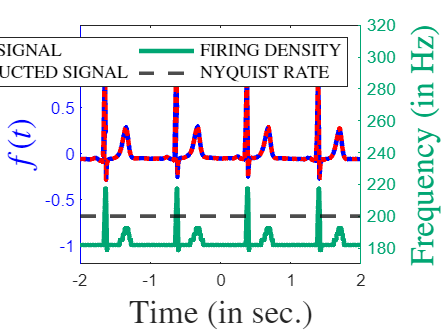

c1 = 1; c = c1;
% === Normalize the signal ===
normalized_fd = (fd ) / c;

% === Compute firing rate (density) as inverse of inter-spike intervals ===
firing_density = 1 ./ time_stamps;                % Instantaneous firing rate
firing_time = (tn(1:end-1) + tn(2:end)) / 2;  % Midpoints for firing

% === Compute derivative and related quantities ===
signal_derivative = gradient(normalized_fd, td);        
mod_signal_derivative = abs(signal_derivative);         
product_term = normalized_fd .* mod_signal_derivative;  

%% === Plot 1: Normalized Signal and Firing Density ===
figure;

% --- Left y-axis: Signal ---
yyaxis left
plot(td(30000:end-30000), normalized_fd(30000:end-30000)-shift, 'b', 'LineWidth', 2.5, 'DisplayName', 'ORIGINAL SIGNAL'); hold on;
plot(td(30000:end-30000), F_est(30000:end-30000,iter)/c1, 'r:', 'DisplayName', 'RECONSTRUCTED SIGNAL', 'LineWidth', 2.5); 
ylabel('$f(t)$', 'Interpreter', 'latex', 'FontSize', 18);

% Set left axis color to blue
ax = gca;
ax.YAxis(1).Color = [0 0 1];   % Blue

% --- Right y-axis: Firing Density ---
yyaxis right
plot(firing_time(545:end-545), firing_density(545:end-547),'Color', '[0 0.65 0.45]', 'LineWidth', 2.5, ...
    'DisplayName', 'FIRING DENSITY');
yline(200, 'k--', 'LineWidth', 2, 'DisplayName', 'NYQUIST RATE');
ylabel('Frequency (in Hz)', 'Interpreter', 'latex', 'FontSize', 18);

% Set right axis color to magenta
ax.YAxis(2).Color = [0 0.65 0.45];   % Magenta

% --- Common axes formatting ---
yyaxis right
ylim([170, 320]);
yyaxis left
ylim([-1.2, 1.4]);

% --- Legend ---
legend('show', 'Interpreter', 'latex', 'FontSize', 10, 'Location', 'northeast', 'NumColumns', 2);

xlabel('Time (in sec.)', 'Interpreter', 'latex', 'FontSize', 18);
xlim([-2, 2]);

%set(gca, 'LooseInset', max(get(gca, 'TightInset'), 0.02))

%exportgraphics(gcf, 'ECG_result.pdf', ...
%    'ContentType', 'vector', ...
%    'BackgroundColor', 'none', ...
%    'Resolution', 300);


disp(min(td))

   -4.9990



disp(max(td))

    4.9990




mean(fd-shift)

ans = 2.8684e-04